
% Define the filename for the .mat file
filename = ["C:\Users\Arif\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Estocasticos\Reto\Fase 3\Datos\p3mean.mat"]

filename = "C:\Users\Arif\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Estocasticos\Reto\Fase 3\Datos\p3mean.mat"

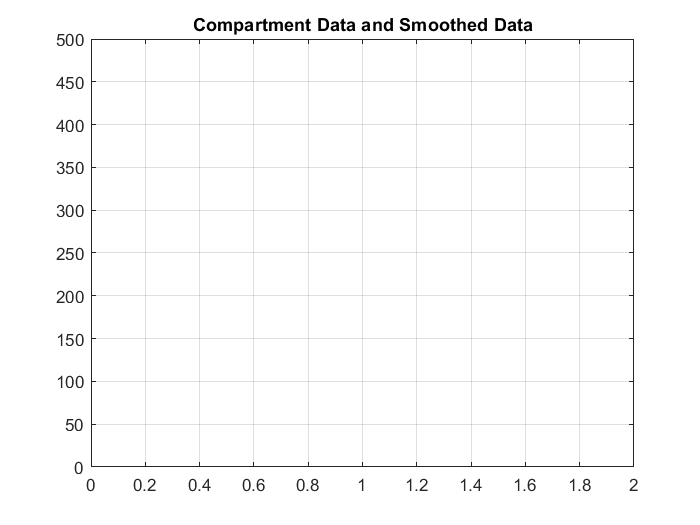

Data = load(filename);

Sr = Data.mean_s(1,:)'; %Data.Ss';   % Susceptible compartment data
Ir = Data.mean_i(2,:)'; %Data.Is';   % Infected compartment data
Rr = Data.mean_r(3,:)';%Data.Rs';   % Recovered compartment data
ts= ones(1,181);
N=round(Sr(1)+Ir(1)+Rr(1));

%Sr = Data.S;   % Susceptible compartment data  
%Ir = Data.I;   % Infected compartment data
%Rr = Data.R;   % Recovered compartment data
%ts = Data.t;   % Time steps
%N= Data.N; 

[Ss , Is , Rs] =smooth(Sr,Ir,Rr,ts,6);


clf
plot(ts,Sr ,'k-',ts ,Ss ,'b',...
     ts, Ir, 'k-', ts, Is, 'r', ...
     ts, Rr, 'k-', ts, Rs, 'g');
grid on
title('Compartment Data and Smoothed Data')
%legend('Original S', 'Smoothed S','Original Exposed', 'Smoothed Exposed', 'Original Infected', 'Smoothed Infected', 'Original Recovered', 'Smoothed Recovered')

hold off


% Specify the filename where you want to save the data
filename = 'SIR3s.mat';

% Use the save function to save the arrays to the .mat file
save(filename, 'Ss', 'Is', 'Rs','ts','N');




data = load("C:\Users\Arif\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Estocasticos\Reto\Fase 3\SIRs1.mat");

% Access the arrays using field names
Ss= data.Ss;
Is = data.Is;
Rs = data.Rs;



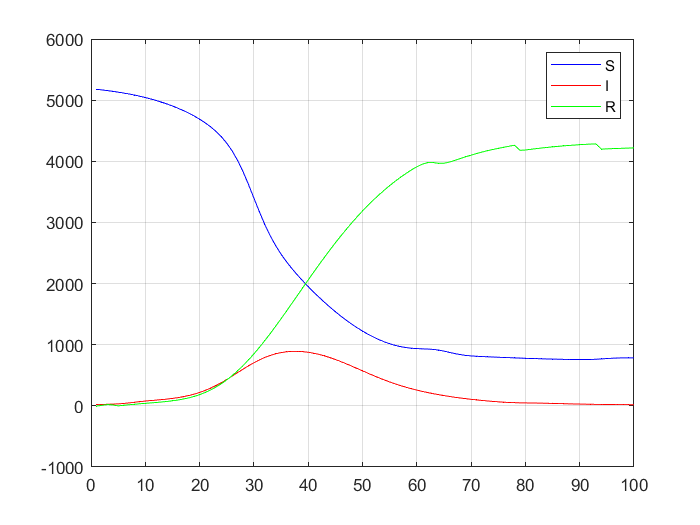

plot(ts,Ss,'b',...
     ts, Is, 'r', ...
     ts, Rs, 'g');
legend("S","I","R")
grid on

function[S, I, R]=smooth(Sr,Ir,Rr,ts,nn)
    % Create a feedforward neural network with one hidden layer containing 20 neurons
    net = feedforwardnet(nn, 'trainlm'); % 'trainlm' is a suitable training algorithm for regression/smoothing
    
    % Set network training parameters
    net.trainParam.show = 50;     % Display progress every 50 iterations
    net.trainParam.lr = 0.05;     % Learning rate
    net.trainParam.epochs = 5000; % Increase the number of training iterations
    net.trainParam.goal = 1e-3;   % Training goal criterion (you can make it smaller for more precise smoothing)
    
    % Prepare the input and target data for smoothing for each compartment
    inputData = ts';   % Time steps as input
    
    
    targetDataSr = Sr';  % Susceptibles compartment data as target
    netSr = train(net, inputData, targetDataSr);  % Train the network
    S = sim(netSr, inputData); 
    
    % Smoothen the Exposed compartment data (Er)
    %targetDataEr = Er';  % Exposed compartment data as target
    %netEr = train(net, inputData, targetDataEr);  % Train the network
    %smoothedDataEr = sim(netEr, inputData);       % Simulation
    
    % Smoothen the Infected compartment data (Ir)
    targetDataIr = Ir';  % Infected compartment data as target
    netIr = train(net, inputData, targetDataIr);  % Train the network
    I = sim(netIr, inputData);       % Simulation
    
    % Smoothen the Recovered compartment data (Rr)
    targetDataRr = Rr';  % Recovered compartment data as target
    netRr = train(net, inputData, targetDataRr);  % Train the network
    R = sim(netRr, inputData);       % Simulation
    
end



